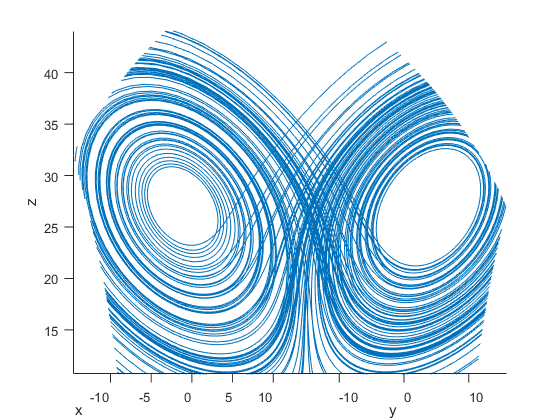

clear all;clc;close all
rho=28;sigma=10;beta=8/3;
%f=@(x,y,z)[sigma*(y-x);x.*(rho-z)-y;x.*y-beta*z];
f=@(t,x)[sigma*(x(2)-x(1));
    x(1).*(rho-x(3))-x(2);
    x(1).*x(2)-beta*x(3)];
x0=[-1,3,4];
t=100;
%[T,X]=ode45(f,[0,30],x0);
% for i=1:9
%     for j=1:9
        [T,X]=rk_4(f,[0,t,0.01],x0);
        plot3(X(:,1),X(:,2),X(:,3))
        view([1,-1,0])
        xlabel('x'),ylabel('y'),zlabel('z')

%     end
% end
a=input('dafad\n')

a = 0.0000 + 1.0000i